##                      This MATLAB Live Script compares analytic and numerical                 solutions of CRPS of P = N(µ,σ2) of Vrugt, WRR (2024)

**Quickly written to verify match of analytic and numerical solutions** 

CRPS(P,w) = w*(2F(w) - 1) - 2 \int_{0}^{1} tau * F^{-1}(tau)d tau + 2 \int_F(w)^1 F^{-1}(tau)d tau

**GEV: Quantile function**

F^{-1}(tau) = mu - s*log(-log(tau))                       if xi = 0

F^{-1}(tau) = mu + s/xi * ( (-log(tau))^-xi - 1 )      if xi > 0 and xi < 0

**Lets first get an analytic expression for the first integral**

- 2 \int_{0}^{1} tau * F^{-1}(tau)d tau

**Integration by parts **

\int udv = u*v - \int v du

if u = tau, then du = 1

if dv = F^{-1}(tau), then v = int(mu + s/xi * ( (-log(tau))^(-xi) - 1 ),tau)

        = 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau)

**Thus**

\int_{0}^{1} tau * F^{-1}(tau)d tau = tau * 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau) - \int 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau)

\int(1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau),tau) = 1/(2*xi) * ( tau*(mu*tau*xi + 2*s*gammaup(1-xi,-log(tau)) - s*tau) - 2^(xi)*s*gammaup(1-xi,-2*log(tau))

**We yield**

\int_{0}^{1} tau * F^{-1}(tau)d tau = [ tau * 1/xi * (mu*xi*tau + s*gammaup(1-xi,-log(tau)) - s*tau) - ( 1/(2*xi) * ( tau*(mu*tau*xi

                                                       + 2*s*gammaup(1-xi,-log(tau)) - s*tau) - 2^(xi)*s*gammaup(1-xi,-2*log(tau)) ) ) ]_{0}^{1}

if dv = F^{-1}(tau), then v = int(mu + sqrt(2) * s * erfinv(2*tau - 1),tau)

                                --> v = mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2))

**Thus**

\int_{0}^{1} tau * F^{-1}(tau)d tau = tau * ( mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2)) ) 

                                                        - \int mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2))

**Then**

int(mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2)) ,tau) = (mu*tau^2)/2 - (s*erf(2^(1/2)*erfinv(2*tau - 1)))/(4*pi^(1/2))

**And we yield**

\int_{0}^{1} tau * F^{-1}(tau)d tau = [ tau * ( mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2)) ) 

                                                        - ( (mu*tau^2)/2 - (s*erf(2^(1/2)*erfinv(2*tau - 1)))/(4*pi^(1/2)) ) ]_{0}^{1}

**Now the second integral of the CRPS quantile decomposition**

\int_F(w)^1 F^{-1}(tau)d tau = \int mu + sqrt(2) * s * erfinv(2*tau - 1)

                                             = [ mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2)) ]_{F(w)}^{1}

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

close all hidden; clear variables; clc

`Define parameter values of the GEV distribution forecast P = GEV(µ,σ2,xi)`

mu = 2;         % mean of normal distribution forecast
s2 = pi;        % variance of normal distribution forecast
n = 1000;       % number of measurements (w = omega)

`No need to change from here on`

s = sqrt(s2);               % MATLAB uses sigma as input to normpdf/normcdf
F_N = @(w) normcdf(w,mu,s); % CDF of normal distribution
f_N = @(w) normpdf(w,mu,s); % PDF of normal distribution

`Sample ensemble from N(µ,σ2) --> for numerical estimate of CRPS`

[fcst_n] = normrnd(mu,s,1000,2000);
% Now use samples to determine min/max for drawing verifying observations
r = range(fcst_n(:));
w_min = min(fcst_n(:)) - r/10; w_max = max(fcst_n(:)) + r/10;
W = unifrnd(w_min,w_max,n,1);
% Initialize some variables for aanlytic computation of CRPS
[crps_an,L,La,R,Ra] = deal(nan(n,2)); [Lt,Rt] = deal(nan(n,1));

% Loop over all measurements
for i = 1:n
    w = W(i); % unpack measurements one at a time
    % Left integral
    % Numerical estimate of left integral - upper bound
    tau = 0.9999;
    L(i,1) = tau * ( mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2)) ...
        / (2*pi^(1/2)) ) - ( (mu*tau^2)/2 - (s*erf(2^(1/2) * ...
        erfinv(2*tau - 1)))/(4*pi^(1/2)) );
    % Analytic estimate of left integral - upper bound
    La(i,1) = mu - ( mu/2 - s/(4*pi^(1/2)));
    % Numerical estimate of left integral - lower bound
    tau = 0.0001;
    L(i,2) = tau * ( mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2)) ...
        / (2*pi^(1/2)) ) - ( (mu*tau^2)/2 - (s*erf(2^(1/2) * ...
        erfinv(2*tau - 1)))/(4*pi^(1/2)) );
    % Analytic estimate of left integral - lower bound
    La(i,2) = - s/(4*pi^(1/2));
    % Analytic value of left integral ( should equal L(i,1) - L(i,2) )
    Lt(i,1) = mu/2 + 2*s/(4*sqrt(pi));
    % Lt(i,1) = mu - ( mu/2 - s/(4*pi^(1/2))) - ( - s/(4*pi^(1/2)));
    
    % Right integral
    % Numerical estimate of right integral - upper bound
    tau = 0.9999;
    R(i,1) = mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2));
    % Analytic estimate of right integral - upper bound
    Ra(i,1) = mu;
    % Numerical estimate of right integral - lower bound
    tau = F_N(w);
    R(i,2) = mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2));
    % Analytic estimate of right integral - lower bound
    Ra(i,2) = mu*F_N(w) - (2^(1/2)*s*exp(-erfinv(2*F_N(w) ...
        - 1)^2))/(2*pi^(1/2));
    % Analytic value of right integral ( should equal R(i,1) - R(i,2) )
    Rt(i,1) = mu - mu*F_N(w) + (2^(1/2)*s*exp(-erfinv(2*F_N(w) ...
        - 1)^2))/(2*pi^(1/2));
    % Now solution in paper: Equation I12
    crps_an(i,1) = s/sqrt(pi) - 2*s^2*f_N(w) - (w-mu)*(2*F_N(w) - 1);
        % = - w*(2*Fn(w) - 1) + 2 * (L(i,1)-L(i,2)) - 2 * (R(i,1)-R(i,2));
        % = - w*(2*Fn(w) - 1) + 2 * Lt(i,1) - 2 * Rt(i,1);
    % Solution from quantile formulation - without simplification
    crps_an(i,2) = - w*(2*F_N(w) - 1) - mu + 2*mu*F_N(w) + s/sqrt(pi) ...
        - 2^(1/2)*s*exp(-erfinv(2*F_N(w) - 1)^2)/sqrt(pi);
    % --> is equal to crps_an(:,1) 
end

% Compute CRPS from ensemble --> numerical estimates
[~,crps_num] = crp_score(fcst_n,W,'weib');

`PLOT RESULTS `

`Plot 1: Scatter plot CRPS from analytic solution and CRPS from ensemble`

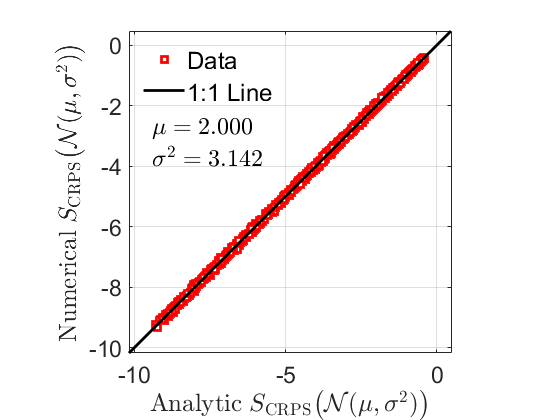

figure(1)
% Plot analytic versus numerical CRPS values
plot(crps_an(:,1),crps_num,'rs','markerfacecolor','w','linewidth',2);
xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
axis square
r = range(crps_an(:,1));
xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
axis([xymin xymax xymin xymax]);
line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
legend boxoff
text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
    char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
    char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
set(gca,'fontsize',17); set(gcf,'color','w'); grid on

% Print some superificial errors to screen
max_err = max(abs(crps_num-crps_an(:,1)));
mean_err = mean(abs(crps_num-crps_an(:,1)));

`Plot 2: Scatter plot analytic and numerical CRPS (from quantile form)`

figure(2)
plot(crps_an(:,2),crps_num,'rs','markerfacecolor','w','linewidth',2);
xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
axis square
r = range(crps_an(:,1));
xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
axis([xymin xymax xymin xymax]);
line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
legend boxoff
text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
    char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
    char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
set(gca,'fontsize',17); set(gcf,'color','w'); grid on

% Print some superificial errors to screen
max_err = max(abs(crps_num-crps_an(:,2))); 
mean_err = mean(abs(crps_num-crps_an(:,2)));